## **CYKLY IDEÁLNÍCH VÍCESTUPŇOVÝCH KOMPRESORŮ**

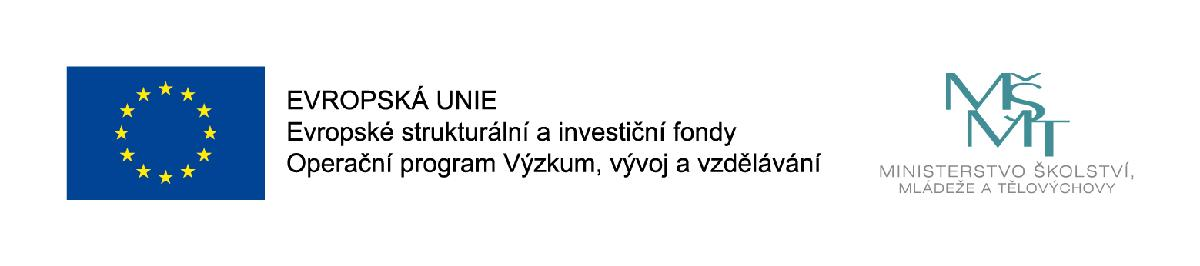

#### prof. Ing. Josef ŠTĚTINA, Ph.D. / Vysoké učení technické v Brně

#### email: [josef.stetina@vutbr.cz](mailto:josef.stetina@vutbr.cz)

#### www: [http://termomechanika.online/](http://termomechanika.online/)

#### www: [http://bit.ly/termomechanika_online/](http://bit.ly/termomechanika_online/)

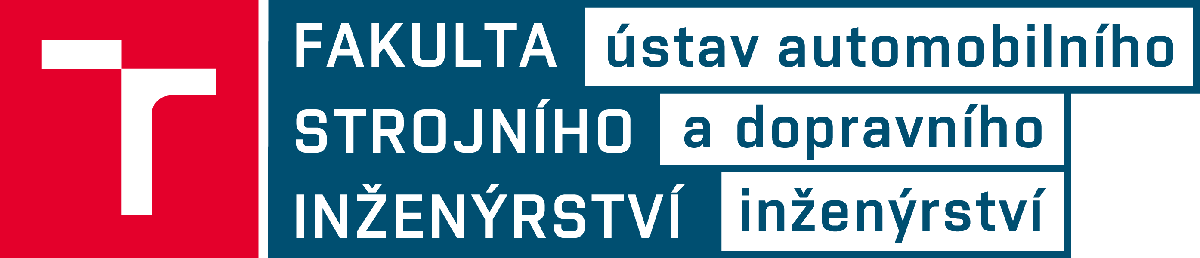

Zpravidla se jednostupňové kom­presory konstruují pro poměr tlaků 6 - 8**, **výjimečně (u malých) až 10.

Pro vyšší kompresní tlaky se pro­vádí komprese ve více stupních tak, že v prvním stupni stlačíme plyn na tlak px*, *který je v druhém stupni (válci) tlakem počátečním. V druhém stupni se plyn komprimuje na tlak, který je opět počátečním tlakem třetího stupně. 

*Stupňová komprese *se provádí tak dlouho, až dosáhneme žádaného tlaku. Se stoupajícím kompresním poměrem roste teplota plynu, která nesmí přesáhnout určitou výši z důvodů bezpečnosti provozu. Proto se mezi jednotlivými stupni stlačený plyn ochlazuje v chladičích na původní teplotu (nebo na teplotu jen o málo vyšší) při konstantním tlaku. Ochlazením se zmenší též objem plynu, tím i rozměry kompresoru. Současně se zmenšuje potřebná kompresní práce a snížením příkonu provozní náklady.

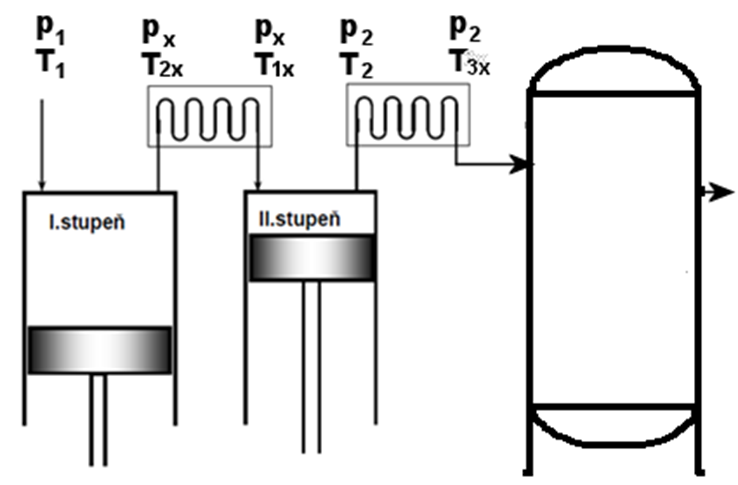

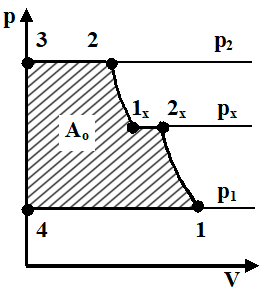        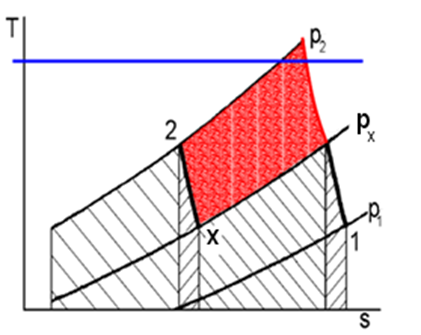

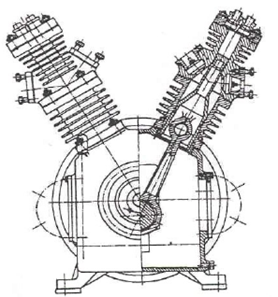


$$\[P = \frac{n}{{n - 1}}\dot mr{T_1}\left[ {1 - {{\left( {\frac{{{p_x}}}{{{p_1}}}} \right)}^{\frac{{n - 1}}{n}}}} \right] + \frac{n}{{n - 1}}\dot mr{T_{1X}}\left[ {1 - {{\left( {\frac{{{p_2}}}{{{p_X}}}} \right)}^{\frac{{n - 1}}{n}}}} \right]\]$$


**Po ochlazení v mezichladiči **na *T**1X** = T**1*


$$\[P{\kern 1pt}  = \frac{n}{{n - 1}}{p_1}{\dot V_1}\left[ {2 - {{\left( {\frac{{{p_x}}}{{{p_1}}}} \right)}^{\frac{{n - 1}}{n}}} - {{\left( {\frac{{{p_2}}}{{{p_x}}}} \right)}^{\frac{{n - 1}}{n}}}} \right]\]$$


**Jelikož požadujeme minimální příkon, **musí být výraz v hranaté závorce minimální. Z takového řešení obdržíme **optimální dělicí tlak ***p**x*.

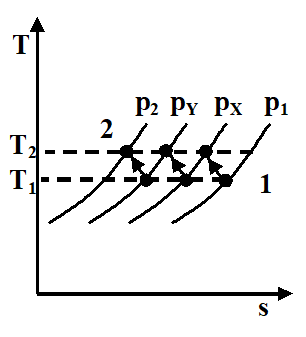


$$$Z{\kern 1pt}  = {\kern 1pt} {\left( {\frac{{{p_x}}}{{{p_1}}}} \right)^{\frac{{n - 1}}{n}}}{\kern 1pt}  + {\kern 1pt} {\left( {\frac{{{p_2}}}{{{p_x}}}} \right)^{\frac{{n - 1}}{n}}}$$$



$$$\frac{{m\,p_X^{m - 1}}}{{p_1^m}} - \frac{{m\,p_2^m}}{{p_X^{m + 1}}} = 0\quad  \Rightarrow \quad p_X^{2m} = p_1^mp_2^m$$$


**Konečný vztah po dělící tlak u dvoustuňový kompresor**


$$${p_X} = \sqrt {{p_1}{p_2}} $$$


Tlakový poměr pro dvoustupňový kompresor


$$\[{\varepsilon _P} = \frac{{{p_X}}}{{{p_1}}} = \frac{{{p_2}}}{{{p_X}}} = \sqrt {\frac{{{p_2}}}{{{p_1}}}} \]$$


**Zobecnění pro vícestupňový kompresor**

# 
$$\[{\varepsilon _P} = \frac{{{p_X}}}{{{p_1}}} = \sqrt[z]{{\frac{{{p_{KONECNY}}}}{{{p_{SACI}}}}}}\]$$


### Postup výpočtu vícestupňového kompresoru.

Výpočet maximálního tlakového poměru:


$$\[{\left( {\frac{{{p_2}}}{{{p_1}}}} \right)_{\max }} = {\left( {\frac{{{T_{2,\max }}}}{{{T_1}}}} \right)^{\frac{n}{{n - 1}}}} = {\varepsilon _{P\max }}\]$$


Výpočet počtu stupňů, výsledek se zaokrouhlí nahoru na celý počet stupňů kompresoru


$$\[{z^,} = \frac{{\log \frac{{{p_2}}}{{{p_1}}}}}{{\log \;{\varepsilon _{P\max }}}}\]$$


Skutečný tlakový poměr nově navrženého z-stupňového kompresoru


$$\[{\varepsilon _P} = \sqrt[z]{{\frac{{{p_2}}}{{{p_1}}}}}\]$$


**Celkový příkon z-stuňového kompresoru:**


$$\[P = \sum {\dot m}  \cdot {a_t} = \frac{n}{{n - 1}}p \cdot \dot V \cdot \left[ {\varepsilon _P^{\frac{{n - 1}}{n}} - 1} \right] \cdot z\]$$


Následujicí kód ukazuje jak počet stupňů kompresoru snižuje teplotu po kompresi. Tedy čím více stuňů, tím více se výsledná teplota přibližuje izotermické kompresi.

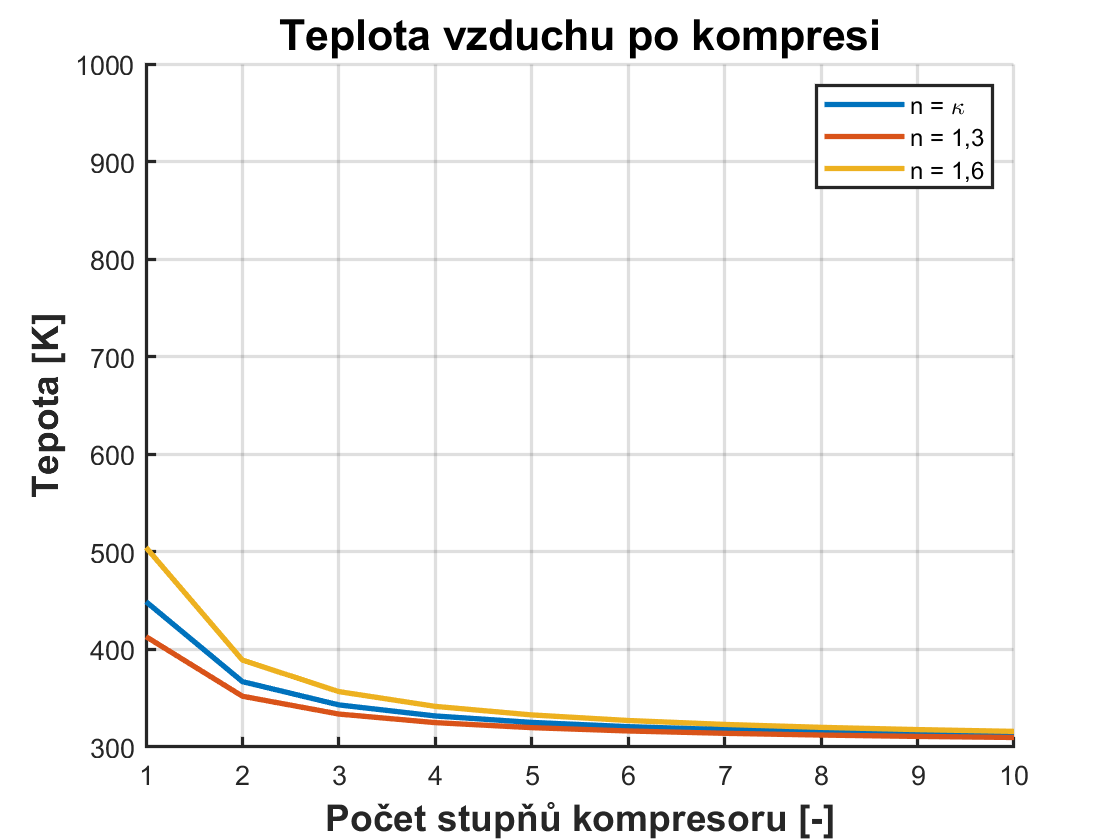

subplot(1,1,1);
i = 1;
zz = zeros(1, 10);
t_1 = zeros(1, 10);
t_2 = zeros(1, 10);
t_3 = zeros(1, 10);
T1 = 300;
for z=1:10
    eps =(p2/p1)^(1/z);
    zz(i) = z;
    %pi_v(i) = pi;
    t_1(i) = T1*eps^((1.41-1)/1.41);
    t_2(i) = T1*eps^((1.3-1)/1.3);
    t_3(i) = T1*eps^((1.6-1)/1.6);
    i = i + 1;
end
title('Teplota vzduchu po kompresi','FontSize', 16 , 'FontName', 'Helvetica','FontWeight','bold');
xlabel('Počet stupňů kompresoru [-]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
ylabel('Tepota [K]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
xlim([1 10]);
ylim([300 1000]);
set(gca, 'linewidth',1.2);
hold on;
plot(zz,t_1,'-','linewidth',2);
plot(zz,t_2,'-','linewidth',2);
plot(zz,t_3,'-','linewidth',2);
grid on;
legend('n = \kappa','n = 1,3','n = 1,6')
hold off;

### Příklad

Požadovaná výkonnost kompresoru je 100 m^3/hod při tlaku 1000 hPa a teplotě 20 °C.  Požadovaný výstupní tlak je 15 MPa, v kompresoru nesmí být překročena teplota 180 °C. Exponent polytropy uvažujete ve všech stupňích  n=1,3. Určet celkový příkon kompresoru, teplotu vzduchu po stlačení. Určete celkový průtok vody potřebný na chazení všech válců kompreseoru, mezichladičů a výstupního chladiče, povolené ohřátí vody 30 °C a výstupní teplata vzduchu ve vzdušníku je 20 °C.

clear all;
p1hPa = 1000; % [hPa]
t1C   = 20;   % [°C]
V1hod = 100;  % [m^3/h]
p2MPa = 15;   % [MPa]
npol  = 1.3;  % [-]
t4C   = 20;   % [°C]
dtvoda = 30;  % [K]
tmax  = 180;  % [°C]

Vlastnosti vzduchu a přepočty

rair  = 287.04; % [J/kgK]
kappa = 1.41;   %  [-]
cpair = kappa/(kappa-1)*rair;
cvair = 1.0/(kappa-1)*rair;
T1 = C2K(t1C);
p1 = hPa2Pa(p1hPa);
p2 = MPa2Pa(p2MPa);
V1 = V1hod / 3600.0;
mdot = p1*V1/(rair*T1);
[cvoda, lamvoda, rovoda ] = vlastnosti_voda(20);  % volíme 20 °C pro teplotu chladicí vody
x = ['Hmotnostní tok vzduch dodávaný kompresorem = ' num2str(mdot,6) ' kg/s.' ];
disp(x);

Hmotnostní tok vzduch dodávaný kompresorem = 0.0330115 kg/s.



$$\[{\left( {\frac{{{p_2}}}{{{p_1}}}} \right)_{\max }} = {\left( {\frac{{{T_{2,\max }}}}{{{T_1}}}} \right)^{\frac{n}{{n - 1}}}} = {\varepsilon _{P\max }}\]$$



$$\[{z^,} = \frac{{\log \frac{{{p_2}}}{{{p_1}}}}}{{\log \;{\varepsilon _{P\max }}}}\]$$



$$\[{\varepsilon _P} = \sqrt[z]{{\frac{{{p_2}}}{{{p_1}}}}}\]$$


Řešení polytropický děj

T2max = C2K(tmax);
epspmax = (T2max/T1)^(npol/(npol-1));
zopt = log(p2/p1)/log(epspmax);
z=ceil(zopt)

z = 3

fprintf('Optimální počet stupňů kompresoru : %.0f \n',z);

Optimální počet stupňů kompresoru : 3 


epsp =(p2/p1)^(1/z);
fprintf('Kompresní poměr v jednoho stupně : %.3f \n',epsp);

Kompresní poměr v jednoho stupně : 5.313 


p2x = p1 * epsp;
T2x = T1*(p2x/p1)^((npol-1)/npol);
p3x = p2x * epsp;
T3x = T1*(p3x/p2x)^((npol-1)/npol);
T2 = T1*(p2/p3x)^((npol-1)/npol);
fprintf('Dělící tlaky v [MPa] : %.3f, %.3f \n',Pa2MPa(p2x), Pa2MPa(p3x));

Dělící tlaky v [MPa] : 0.531, 2.823 


fprintf('Teploty po kompresy [°C] : %.1f, %.1f \n',K2C(T2x), K2C(T3x));

Teploty po kompresy [°C] : 157.9, 157.9 


V2 = mdot*rair*T2/p2;
V2x = mdot*rair*T2x/p2x;
V2x2 = mdot*rair*T1/p2x;
V3x = mdot*rair*T3x/p3x;
V3x2 = mdot*rair*T1/p3x;
Ptc1= npol/(npol-1)*p1*V1*(1-(p2x/p1)^((npol-1)/npol));
Ptc2= npol/(npol-1)*p1*V1*(1-(p3x/p2x)^((npol-1)/npol));
Ptc3= npol/(npol-1)*p1*V1*(1-(p2/p3x)^((npol-1)/npol));
Pt = Ptc1 + Ptc2 + Ptc3;
Ptc= npol/(npol-1)*p1*V1*(1-(epsp)^((npol-1)/npol))*z;
x = ['Příkon kompresoru polytropický děj =' num2str(Ptc/1000.0,4) ' kW.' ];
disp(x);

Příkon kompresoru polytropický děj =-16.98 kW.


Qdot1 = (kappa-npol)/(npol*(kappa-1)) * abs(Ptc1);
Qdot2 = (kappa-npol)/(npol*(kappa-1)) * abs(Ptc2);
Qdot3 = (kappa-npol)/(npol*(kappa-1)) * abs(Ptc3);
Qdot4 = mdot * cpair * (T2x-T1);
Qdot5 = mdot * cpair * (T3x-T1);
%Qdotc = (kappa-npol)/(npol*(kappa-1)) * abs(Ptc) + mdot * cpair * (T2x-T1);
Qdocsuma = Qdot1 + Qdot2 + Qdot3 + Qdot4 + Qdot5;
Vdotvodc = Qdocsuma/(cvoda*rovoda*dtvoda);
x = ['Průtok vody pro chlazení kompresoru a chladiče =' num2str(Vdotvodc*1000.0*60,4) ' l/min' ];
disp(x);

Průtok vody pro chlazení kompresoru a chladiče =5.964 l/min


#### Grafický výstup, porovnání

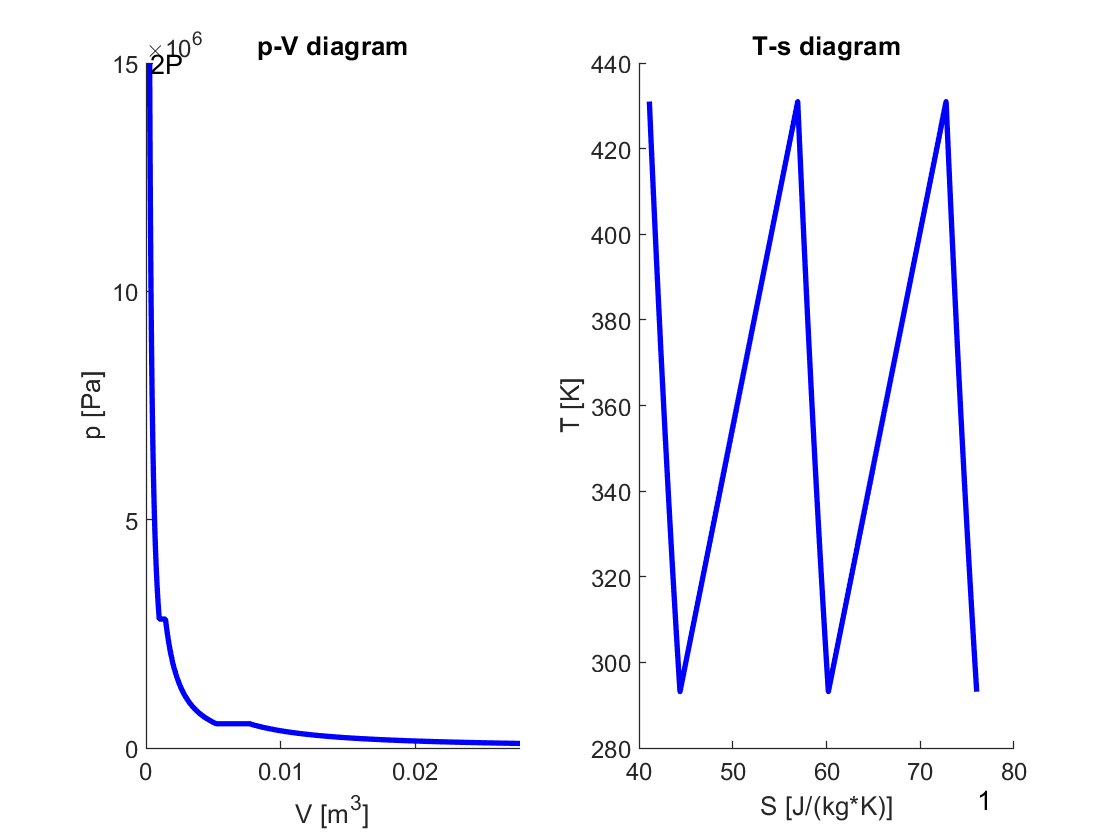

Vvc = zeros([1,180]);
Vwork = linspace(V1,V2x,60);
pvc = zeros([1,180]);
Tvc = zeros([1,180]);
Svc = zeros([1,180]);

pvc(1) = p1;
Tvc(1) = pvc(1) *Vwork(1) / (rair * mdot);
Svc(1)=mdot*cpair*log(Tvc(1))-mdot*rair*log(pvc(1));
for i=2:60
  Vvc(i) = Vwork(i);
  pvc(i) = p1*V1^npol/Vvc(i)^npol;
  Tvc(i) = pvc(i) * Vvc(i) / (rair * mdot);
  Svc(i)=mdot*cpair*log(Tvc(i))-mdot*rair*log(pvc(i));
end

pvc(60) = p2x;
Vvc(1) = V1;
Vvc(60) = V2x;

%suma = 0;
%for i = 1:59
%  suma = (pvc(i) - pvc(i+1))*(Vvc(i) + Vvc(i+1))/2.0;
%end
pvc(61) = p2x;
Vvc(61) = V2x2;
Tvc(61) = T1;
Svc(61)=mdot*cpair*log(Tvc(61))-mdot*rair*log(pvc(61));

Vwork = linspace(V2x2,V3x,60);
for i=2:60
  Vvc(60+i) = Vwork(i);
  pvc(60+i) = p2x*V2x2^npol/Vwork(i)^npol;
  Tvc(60+i) = pvc(60+i) * Vwork(i) / (rair * mdot);
  Svc(60+i)=mdot*cpair*log(Tvc(60+i))-mdot*rair*log(pvc(60+i));
end
pvc(120) = p3x;
Vvc(120) = V3x;
Tvc(120) = pvc(120) * Vvc(120) / (rair * mdot);

%suma = 0;
%for i = 61:119
%  suma = (pvc(i) - pvc(i+1))*(Vvc(i) + Vvc(i+1))/2.0;
%end
Svc(120)=mdot*cpair*log(Tvc(120))-mdot*rair*log(pvc(120));
pvc(121) = p3x;
Vvc(121) = V3x2;
Tvc(121) = T1;
Svc(121)=mdot*cpair*log(Tvc(121))-mdot*rair*log(pvc(121));
Vwork = linspace(V3x2,V2,60);
for i=2:60
  Vvc(120+i) = Vwork(i);
  pvc(120+i) = p3x*V3x2^npol/Vwork(i)^npol;
  Tvc(120+i) = pvc(120+i) * Vwork(i) / (rair * mdot);
  Svc(120+i)=mdot*cpair*log(Tvc(120+i))-mdot*rair*log(pvc(120+i));
end

%suma = 0;
%for i = 120:179
%  suma = (pvc(i) - pvc(i+1))*(Vvc(i) + Vvc(i+1))/2.0;
%end
% Vykreslení diagramu
figure;
subplot(1,2,1);
hold on;
plot(Vvc,pvc,'b-','linewidth',2);
hold off;
% popis bodů diagramu
axis([0 V1 0 p2]);
text(Vvc(180),pvc(180)-0.2,'2P');
% název grafu a popisy os
title('p-V diagram')
xlabel('V [m^3]')
ylabel('p [Pa]')                     
subplot(1,2,2);
hold on;
plot(Svc,Tvc,'b-','linewidth',2);
hold off;
% popis bodů diagramu
text(Svc(1),Tvc(1)-25,'1');
% název grafu a popisy os
title('T-s diagram')
xlabel('S [J/(kg*K)]')
ylabel('T [K]');                      % ^\circC

### Lokální funkce 

Převádí teplotu ve stupních Celsia na Kelvíny

function [K] = C2K(C)
K = C+273.15;
end

Převádí hektoPascaly na Pascaly

function [Pa] = hPa2Pa(hPa)
Pa = hPa*100;
end

Převod

function [m3] = l2m3(l)
m3 = l*.001;
end

Převod

function [kPa] = Pa2kPa(Pa)
kPa = Pa/1000;
end

Převod

function [kW] = W2kW(W)
kW = W/1000;
end

Převod

function [mm] = m2mm(m)
mm = m*1000;
end

Převod

function [MPa] = Pa2MPa(Pa)
MPa = Pa*0.000001;
end

Převod

function [C] = K2C(K)
C = K-273.15;
end

Výpočet termofyzikálních vlastností vody

function [kapacita, vodivost, hustota ] = vlastnosti_voda(teplota)
if teplota < 0.0
    error('Teplota nemuze byt zaporna');
end
hustota = 1006 - 0.26*teplota-0.0022*teplota^2;
kapacita = 4210-1.363*teplota+0.014*teplota^2;
vodivost = 0.555+0.00263*teplota-15.7e-6*teplota^2+27.3e-9*teplota^3;
end

function [Pa] = MPa2Pa(MPa)
Pa = MPa*1000000.0;
end